% Load dataset
load Dataset_task2.mat;

% Extract the relevant columns
X = short_matrix_no_id(:, [6 7 1]);

% Normalize the features
X_norm = normalize(X);

% Perform k-means clustering with k = 10
k = 10;
[idx, centers] = kmeans(X_norm, k);

% Assign a new ID to each cluster
new_ids = (1:k)';
cluster_ids = new_ids(idx);

% Replace the original IDs in the dataset with the new IDs
short_matrix_no_id(:, [6 7 1]) = [cluster_ids X_norm];








































% Extract inputs and targets
Inputs = short_matrix_no_id;
Inputs = fillmissing(Inputs, 'nearest');
Targets = Inputs(:, 16);
Inputs(:, 3) = [];
Inputs(:, 2) = [];
% Define network architecture
hiddenLayerSize = 50;
net = fitnet(hiddenLayerSize, 'trainbr'); % 'trainbr' for Bayesian regularization

% Set training options
net.trainParam.showWindow = false;
net.trainParam.epochs = 100;

% Train the network
[net, tr] = train(net, Inputs', Targets');

% Test the network on the dataset
outputs = net(Inputs');
outputs

outputs =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    1.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


mse = mean((Targets' - outputs).^2);
fprintf('Mean squared error: %.2f\n', mse);

Mean squared error: 0.00


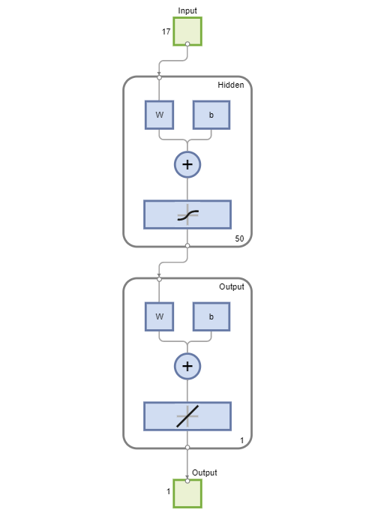


% Visualize the network
view(net);